## Plot nanobots from CSV file of BloodvoyagerS

clc
clear all
close all

## Loading data

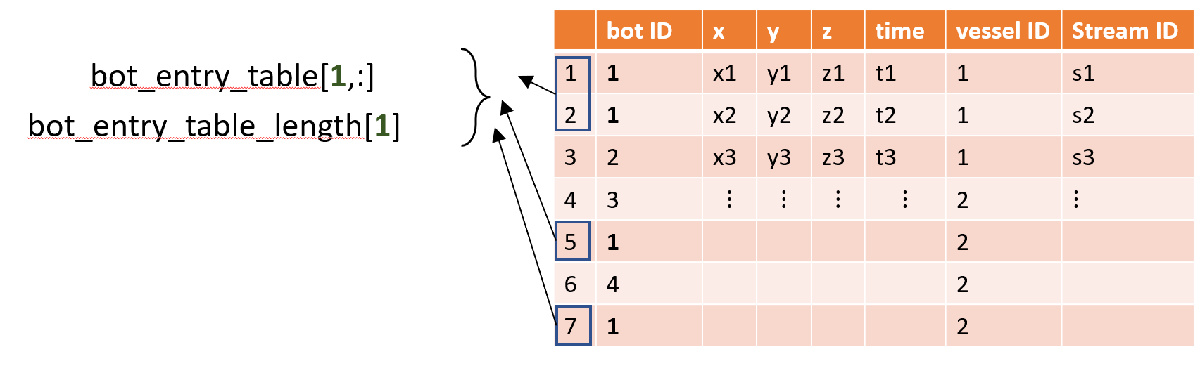

dataAmountPercent=40;%percentage of the amount of data to read in the range (1 100]

data_file_selector=1;
data_files ={'csvNano_1000bots_500s.csv','1000Bots_500s_3accuracy.csv','1000Bots_8000s_3accuracy','1000Bots_10000s_1accuracy'};

opts=detectImportOptions('csvNano_1000bots_500s.csv');
preview(data_files{data_file_selector},opts) %data file preview

ans = 8×7 table
    Var1    Var2     Var3    Var4    Var5    Var6    Var7
    ____    _____    ____    ____    ____    ____    ____

     15         0       0     2       0       1       0  
     36         0       0     2       0       1       0  
     87         0       0     2       0       1       0  
     95         0       0     2       0       1       0  
    101     -0.06    0.08     2       0       1       0  
    104     -0.06    0.08     2       0       1       0  
    110     -0.06    0.08     2       0       1       0  
    196     -0.06    0.08     2       0       1       0  



botID_column=1;%position in the table for the bot ID
vesselID_column=6;%position in the table for the vessel ID


%reading the IDs and segments only
opts.SelectedVariableNames=[botID_column,vesselID_column];
ids_segments=readmatrix(data_files{data_file_selector},opts);
ids_segments=ids_segments(1:round(dataAmountPercent/100*length(ids_segments)),:);

%identifying the total of vessels ID
segments_unique=unique(ids_segments(:,2));
total_vesselsID=length(unique(segments_unique));
vessels_ID=zeros(1,total_vesselsID);
%labeling the tissues versus circuits
%Upper Body
vessels_ID(9)=1;%Head
vessels_ID(17)=2;%Left Shoulder
vessels_ID(11)=3;%Right Shoulder
vessels_ID(23)=4;%Left Hand
vessels_ID(15)=5;%Right Hand
vessels_ID(29)=6;%Left Elbow
vessels_ID(21)=7;%Right Elbow
vessels_ID(33)=8;%Left Hand
vessels_ID(27)=9;%Right Hand
%Center Body
vessels_ID(24)=10;%Chest and Back
vessels_ID(30)=11;%Spleen
vessels_ID(40)=12;%Kidneys
vessels_ID(36)=13;%Liver
vessels_ID(39)=14;%Intestine
%Lower Body
vessels_ID(49)=15;%Left Hip
vessels_ID(52)=16;%Right Hip
vessels_ID(47)=17;%Left Pelvis and Genitales
vessels_ID(51)=18;%Right Pelvis and Genitales
vessels_ID(54)=19;%Left Knee
vessels_ID(56)=20;%Right Knee
vessels_ID(59)=21;%Left Foot
vessels_ID(60)=22;%Right Foot

%labeling the circuits in HCS
circuits_tissues=[%Upper Body
          9 ...%Head
          17 ...%Left Shoulder 
          11 ...%Right Shoulder          
          23 ...%Left Upper Arm
          15 ...%Right Upper Arm          
          29 ...%Left Elbow
          21 ...%Right Elbow
          33 ...%Left Hand
          27 ...%Right Hand           
          ...%Center Body
          24 ...%Chest and back
          30 ...%Spleen
          40 ...%Kidneys
          36 ...%Liver
          39 ...%Intestine
          ...%Lower Body
          49 ...%Left Hip
          52 ...%Right Hip
          47 ...%Left Pelvis and Genitales
          51 ...%Right Pelvis and Genitales
          54 ...%Left Knee
          56 ...%Right Knee
          59 ...%Left Foot
          60 ...%Right Foot
          ];

%detecting total of bots in the system
ids=ids_segments(:,1);
ids_unique=unique(ids);
total_bots=length(ids_unique);
%detecting total of iterations
total_time=length(find(ids_segments(:,1)==ids_unique(1)))-1;%in seconds

%detecting nanobots per circuit
ids_circuit=cell(1,length(circuits_tissues)+1);
for c=1:length(circuits_tissues)
    ids_circuit{c}=find(ids_segments(:,2)==c);
end


## Looking for entries per bot

%getting entries in the table per nanobot according to their IDs
t_initial=1;
bot_entry_table=zeros(total_bots,total_time-t_initial+1);
bot_entry_table_length=zeros(1,total_bots);
for i=1:total_bots
    bot_found=find(ids==i);
    bot_entry_table(i,1:length(bot_found))=bot_found;
    bot_entry_table_length(i)=length(bot_found);
end
total_time=min(bot_entry_table_length); %updating the total of iterations, not all bots have equal total of iterations
bot_entry_table=bot_entry_table(:,t_initial:total_time);% updating the entry table length
clear ids;

## ID Trayectory per both

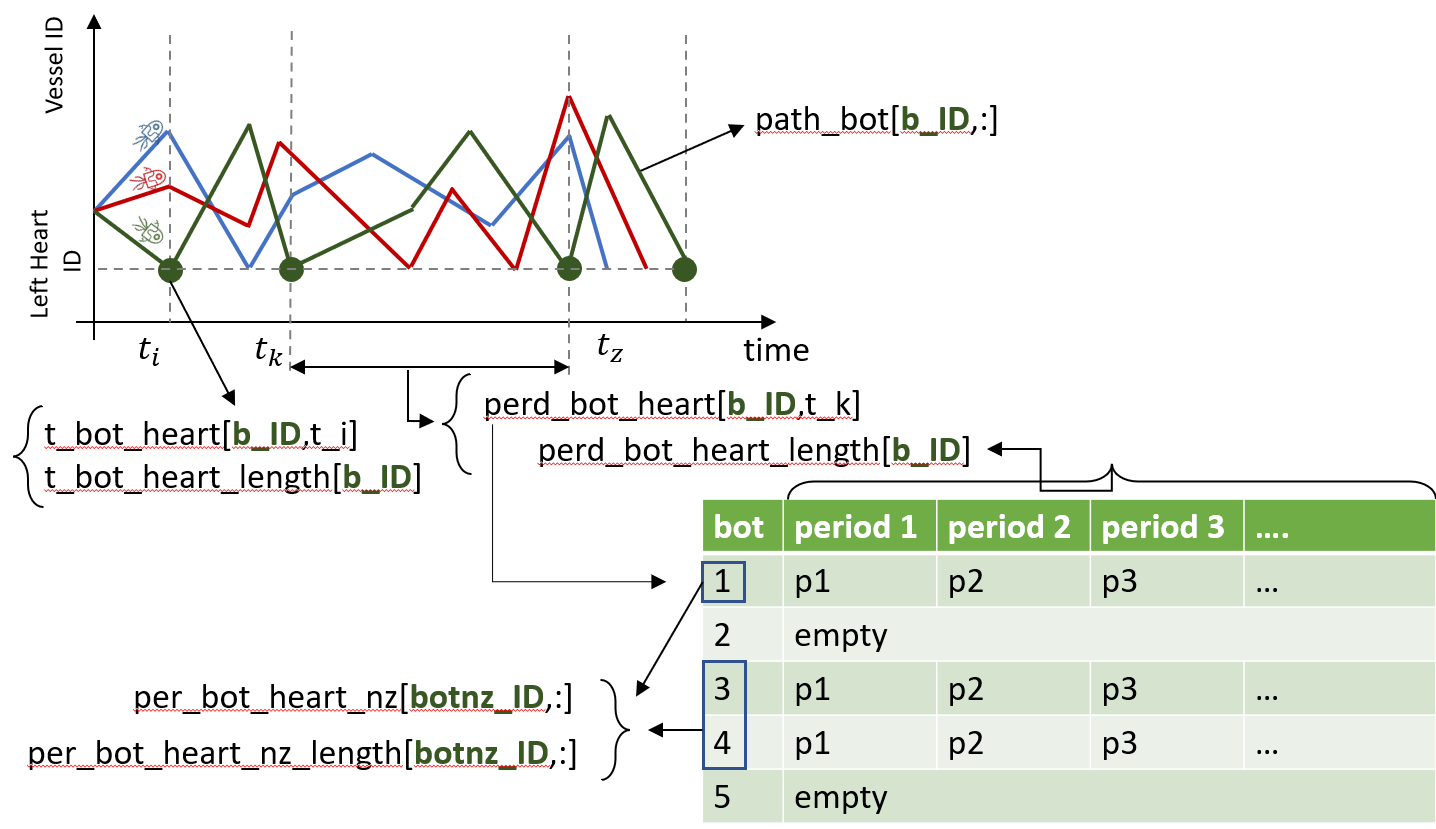

%superposing all the time stamps
path_bot=zeros(total_bots,total_time-t_initial+1);
opts.SelectedVariableNames=vesselID_column;%reading the vessels' ID only
data_vesselsID=readmatrix(data_files{data_file_selector},opts)

data_vesselsID =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



for i=1:total_bots
    path_bot(i,:)=data_vesselsID(bot_entry_table(i,:));
end

clear data_vesselsID;

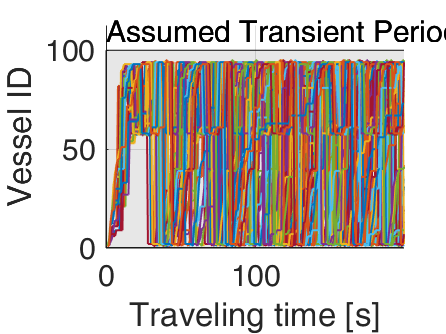

close;
figure;
font=15;
p=patch([0 200 200 0],[0 0 100 100],[0.3010 0.7450 0.9330],"EdgeColor",uint8([17 17 17]),"FaceColor",uint8([17 17 17]));hold on;
set(p,'FaceAlpha',0.1);
for i=1:100
    plot(path_bot(i,:),'LineWidth',1); hold on;
end

text([0,0],[110,110],{'Assumed Transient Period'},'FontSize',font);
grid on;
xlabel('Traveling time [s]');
ylabel('Vessel ID')
axis([0 total_time-t_initial 0 1.2*total_vesselsID]);
% legend('bot 1','bot 2','bot 3');
set(gca,'FontSize',font);

## Computing the traveling time (heart to heart)[ left Heart vessel ID=2 ](https://github.com/RegineWendt/blood-voyager-s/blob/master/Images/table1.pdf)

heart_vessel_ID=2;%left heart
t_bot_heart_temp=zeros(total_bots,total_time-t_initial+1);%time instants when the nanobot is in the Heart
t_bot_heart_lenght_temp=zeros(1,total_bots);%time instants when the nanobot is in the Heart
perd_bot_heart_temp=zeros(total_bots,total_time-t_initial+1);%period of time traveling from the Heart to the Heart
perd_bot_heart_length_temp=zeros(1,total_bots);%total of times passing through the Heart
perd_bot_heart_nz_temp=zeros(1,total_bots);%identify the bots passing through the Heart at least once
perd_bot_heart_nz_length_temp=0;%total of bots passing through the Heart at least once
z=1;
for bot=1:total_bots
    t_vector=find(path_bot(bot,:)==heart_vessel_ID);
    period=filter([1 -1],1,t_vector);
    t_bot_heart_temp(bot,1:length(t_vector))=t_vector;
    t_bot_heart_lenght_temp(bot)=length(t_vector);
    perd_bot_heart_temp(bot,1:length(period)-1)=period(2:end);
    perd_bot_heart_length_temp(bot)=length(period);
    if(perd_bot_heart_length_temp(bot)~=0)
        perd_bot_heart_nz_temp(z)=bot;
        perd_bot_heart_nz_length_temp=z;
        z=z+1;
    end
end

%removing periods' intervals equal to 1
t_bot_heart=zeros(total_bots,total_time-t_initial+1);%time instants when the nanobot is in the Heart
t_bot_heart_lenght=zeros(1,total_bots);%time instants when the nanobot is in the Heart
perd_bot_heart=zeros(total_bots,total_time-t_initial+1);%period of time traveling from the Heart to the Heart
perd_bot_heart_length=zeros(1,total_bots);%total of times passing through the Heart
perd_bot_heart_nz=zeros(1,total_bots);%identify the bots passing through the Heart at least once
perd_bot_heart_nz_length=0;%total of bots passing through the Heart at least once

t_bot_heart(:,1)=t_bot_heart_temp(:,1);
for bot=1:total_bots
    z=1;
    for t=2:(total_time-t_initial+1)
        if(perd_bot_heart_temp(bot,t)>1)
            t_bot_heart(bot,z)=t_bot_heart_temp(bot,t);
            perd_bot_heart(bot,z)=perd_bot_heart_temp(bot,t);
            z=z+1;
        end
    end
    t_bot_heart_lenght(bot)=z-1;
    perd_bot_heart_length(bot)=z-1;
end

%superposing all the time stamps
period_total=zeros(1,sum(perd_bot_heart_length));

x1=1;
for i=1:perd_bot_heart_nz_length
    x2=x1+perd_bot_heart_length(perd_bot_heart_nz(i))-1;
    period_total(x1:x2)=perd_bot_heart(perd_bot_heart_nz(i),1:perd_bot_heart_length(perd_bot_heart_nz(i)));
    x1=x2+1;
end

## Computing the concentration level per nanosensor per time instant

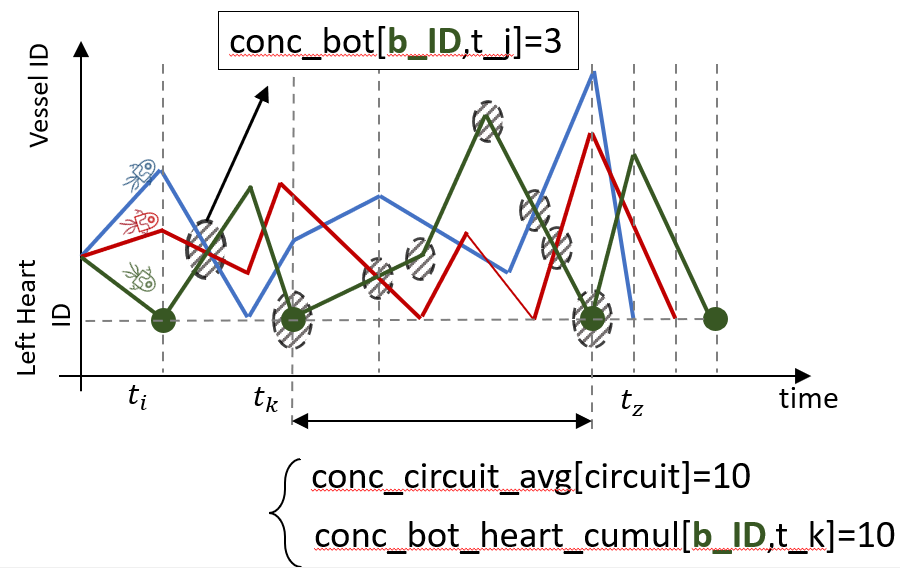

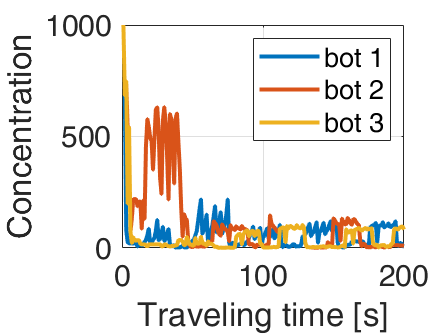

%Computing the total of nanosensors in the same vessel ID per iteration time
conc_bot=zeros(total_bots,total_time-t_initial+1);
for bot=1:total_bots
    for t=1:total_time-t_initial+1
        sample=path_bot(bot,t);
        conc_bot(bot,t)=length(find(path_bot(:,t)==sample));
    end
end

figure;
for bot=1:3
    plot(conc_bot(bot,:),'LineWidth',2); hold on;
end
grid on;
xlabel('Traveling time [s]');
ylabel('Concentration')
legend('bot 1','bot 2','bot 3');
% axis([0 total_time 0 total_vesselsID]);
set(gca,'FontSize',font);

## Computing the cumulative and average concentration level reported at the Heart

conc_bot_heart_cumul=zeros(perd_bot_heart_nz_length,total_time-t_initial+1);
conc_bot_heart_avg=zeros(perd_bot_heart_nz_length,total_time-t_initial+1);
for bot=1:total_bots
%     bot=perd_bot_heart_nz(i);
    t_bot_heart_vector=t_bot_heart(bot,:);
    %accumulating
    cumul=0;
    for j=1:perd_bot_heart_length(bot)-1
        t1=t_bot_heart_vector(j);
        t2=t_bot_heart_vector(j+1);
        conc_bot_heart_cumul(bot,j)=sum(conc_bot(bot,t1:t2));
        conc_bot_heart_avg(bot,j)=mean(conc_bot(bot,t1:t2));
    end
    
end

## Identifying the path per bot along their traveling circuit

path_per_bot=zeros(total_bots,total_time-t_initial+1);

for bot=1:total_bots
    for t=1:t_bot_heart_lenght(bot)

        t_heart_1=t_bot_heart(bot,t);
        t_heart_2=t_heart_1+perd_bot_heart(bot,t);
        for c=1:length(circuits_tissues)
            c_period=find(path_bot(bot,t_heart_1:t_heart_2)==circuits_tissues(c));
            if (~isempty(c_period))
                path_per_bot(bot,t)=circuits_tissues(c);
                break;
            end
        end
    end
end

## Computing delay, cumul concentration, avg concentration, avg concentration curves per circuit


delay_circuit=cell(1,length(circuits_tissues));
conc_cumul_circuit=cell(1,length(circuits_tissues));
conc_avg_circuit=cell(1,length(circuits_tissues));
path_circuit_avg=cell(1,length(circuits_tissues));
path_delay=zeros(1,total_time-t_initial+1);
path_conc_cumul=zeros(1,total_time-t_initial+1);
path_conc_avg=zeros(1,total_time-t_initial+1);

for c=1:length(circuits_tissues)
    first_entry=1;
    z=1;
    for bot=1:total_bots
        index_circ=find(path_per_bot(bot,:)==circuits_tissues(c));
        for j=1:length(index_circ)
            t_1=t_bot_heart(bot,index_circ(j));
            t_2=t_1+perd_bot_heart(bot,index_circ(j));

            path_conc_cumul(z)=conc_bot_heart_cumul(bot,index_circ(j));
            path_conc_avg(z)=conc_bot_heart_avg(bot,index_circ(j));
            path_delay(z)=t_2-t_1+1;%length(path_bot(bot,t_1:t_2));
            z=z+1;
            if(first_entry)
                path_circuit_avg{c}=path_bot(bot,t_1:t_2);
            else
                path_circuit_avg{c}=1/2*(path_circuit_avg{c}+path_bot(bot,t_1:t_2));
                first_entry=0;
            end
        end
    end
    delay_circuit{c}=path_delay(1:z-1);
    conc_cumul_circuit{c}=path_conc_cumul(1:z-1);
    conc_avg_circuit{c}=path_conc_avg(1:z-1);
end


## Plotting the delay per Tissue

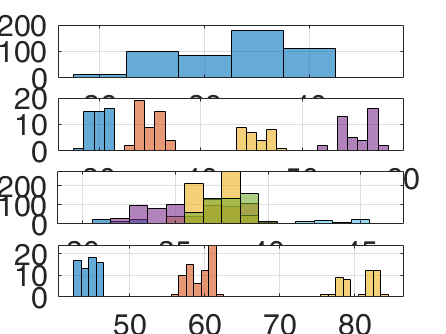


figure;
%Head
subplot 411;
c=9;%Head
histogram(delay_circuit{vessels_ID(c)})
grid on
ylabel('samples');
% axis([20 90 0 1000]);
% legend('Head','Shoulder','Upper Arm','Elbow','Hand');
set(gca,'FontSize',font);

subplot 412;
%Upper Body
c=11;%Right Shoulder
histogram(delay_circuit{vessels_ID(c)}); hold on;
c=15;%Right Upper Arm 
histogram(delay_circuit{vessels_ID(c)});
c=21;%Right Elbow
histogram(delay_circuit{vessels_ID(c)});
c=27;%Right Hand 
histogram(delay_circuit{vessels_ID(c)});
grid on
% axis([20 90 0 500]);
% legend('Head','Shoulder','Upper Arm','Elbow','Hand');
set(gca,'FontSize',font);

subplot 413;
%Center Body
c=24; %Chest and back
histogram(delay_circuit{vessels_ID(c)}); hold on;
c=30; %Spleen
histogram(delay_circuit{vessels_ID(c)});
c=40;%Kidneys
histogram(delay_circuit{vessels_ID(c)});
c=36;%Liver
histogram(delay_circuit{vessels_ID(c)});
c=39;%Intestine
histogram(delay_circuit{vessels_ID(c)});
c=47;%Pelvis
histogram(delay_circuit{vessels_ID(c)});
grid on
% axis([20 90 0 1000]);
set(gca,'FontSize',font);

subplot 414;
%Lower Body
c=49;%Left Hip
histogram(delay_circuit{vessels_ID(c)}); hold on;
c=54;%Left Knee
histogram(delay_circuit{vessels_ID(c)});
c=59;%Left Foot
histogram(delay_circuit{vessels_ID(c)});

grid on
% axis([20 90 0 100]);
xlabel('Traveling time [s]');
set(gca,'FontSize',font);

## Plotting the cumulative conc per Tissue

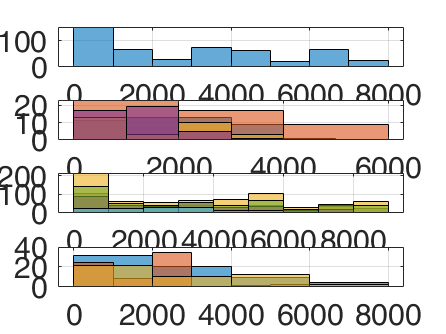


figure;
%Head
subplot 411;
c=9;%Head
histogram(conc_cumul_circuit{vessels_ID(c)})
grid on
ylabel('samples');
% axis([20 90 0 1000]);
% legend('Head','Shoulder','Upper Arm','Elbow','Hand');
set(gca,'FontSize',font);

subplot 412;
%Upper Body
c=11;%Right Shoulder
histogram(conc_cumul_circuit{vessels_ID(c)}); hold on;
c=15;%Right Upper Arm 
histogram(conc_cumul_circuit{vessels_ID(c)});
c=21;%Right Elbow
histogram(conc_cumul_circuit{vessels_ID(c)});
c=27;%Right Hand 
histogram(conc_cumul_circuit{vessels_ID(c)});
grid on
% axis([20 90 0 500]);
% legend('Head','Shoulder','Upper Arm','Elbow','Hand');
set(gca,'FontSize',font);

subplot 413;
%Center Body
c=24; %Chest and back
histogram(conc_cumul_circuit{vessels_ID(c)}); hold on;
c=30; %Spleen
histogram(conc_cumul_circuit{vessels_ID(c)});
c=40;%Kidneys
histogram(conc_cumul_circuit{vessels_ID(c)});
c=36;%Liver
histogram(conc_cumul_circuit{vessels_ID(c)});
c=39;%Intestine
histogram(conc_cumul_circuit{vessels_ID(c)});
c=47;%Pelvis
histogram(conc_cumul_circuit{vessels_ID(c)});
grid on
% axis([20 90 0 1000]);
set(gca,'FontSize',font);

subplot 414;
%Lower Body
c=49;%Left Hip
histogram(conc_cumul_circuit{vessels_ID(c)}); hold on;
c=54;%Left Knee
histogram(conc_cumul_circuit{vessels_ID(c)});
c=59;%Left Foot
histogram(conc_cumul_circuit{vessels_ID(c)});

grid on
% axis([20 90 0 100]);
xlabel('Cumulative concentration');
set(gca,'FontSize',font);

## Plotting avg concentration curves per Body Region

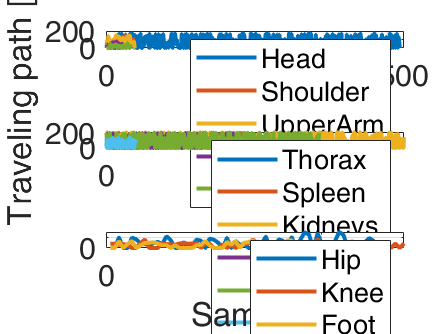

figure;
bins=100;
subplot 311
c=9;%Head
plot(conc_avg_circuit{vessels_ID(c)},'LineWidth',2); hold on;
%Upper Body
c=11;%Right Shoulder
plot(conc_avg_circuit{vessels_ID(c)},'LineWidth',2);
c=15;%Right Upper Arm 
plot(conc_avg_circuit{vessels_ID(c)},'LineWidth',2);
c=21;%Right Elbow
plot(conc_avg_circuit{vessels_ID(c)},'LineWidth',2);
c=27;%Right Hand 
plot(conc_avg_circuit{vessels_ID(c)},'LineWidth',2);
legend('Head','Shoulder','UpperArm','Elbow','Hand');
set(gca,'FontSize',font);
grid on;
% axis([0 90 0 100]);
ylabel('Traveling path [vessel ID]')

%Center Body
subplot 312
c=24; %Chest and back
plot(conc_avg_circuit{vessels_ID(c)},'LineWidth',2); hold on;
c=30; %Spleen
plot(conc_avg_circuit{vessels_ID(c)},'LineWidth',2);
c=40;%Kidneys
plot(conc_avg_circuit{vessels_ID(c)},'LineWidth',2);
c=36;%Liver
plot(conc_avg_circuit{vessels_ID(c)},'LineWidth',2);
c=39;%Intestine
plot(conc_avg_circuit{vessels_ID(c)},'LineWidth',2);
c=47;%Pelvis
plot(conc_avg_circuit{vessels_ID(c)},'LineWidth',2);
legend('Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis');
set(gca,'FontSize',font);
grid on;
% axis([0 90 0 100]);

subplot 313
%Lower Body
c=49;%Left Hip
plot(conc_avg_circuit{vessels_ID(c)},'LineWidth',2);hold on;
c=54;%Left Knee
plot(conc_avg_circuit{vessels_ID(c)},'LineWidth',2);
c=59;%Left Foot
plot(conc_avg_circuit{vessels_ID(c)},'LineWidth',2);
legend('Hip','Knee','Foot');
set(gca,'FontSize',font);
grid on;
% axis([0 90 0 100]);
xlabel('Samples');

## Computing cross-correlation per circuit


conc_cross_circuit=cell(length(circuits_tissues));

path_cross_corr=zeros(1,total_time-t_initial+1);


flag=0;
for c=1:length(circuits_tissues)
    z=1;
    for bot=1:total_bots
        index_circ=find(path_per_bot(bot,:)==circuits_tissues(c));
        if(~isempty(index_circ))
            for j=1:length(index_circ)
                t_1=t_bot_heart(bot,index_circ(j));
                t_2=t_1+perd_bot_heart(bot,index_circ(j));
                cross_temp=xcorr(conc_bot(bot,t_1:t_2),conc_avg_circuit{c});
                %computing cross-corr when evaluating it at its maximum
                path_cross_corr(z)=max(cross_temp);
                z=z+1;
                flag=1;
            end
        end        
    end
    if(flag)
        conc_cross_circuit{c}=path_cross_corr(1:z-1);
        flag=0;
    end
        
end


## Plotting cross-correlation per circuit

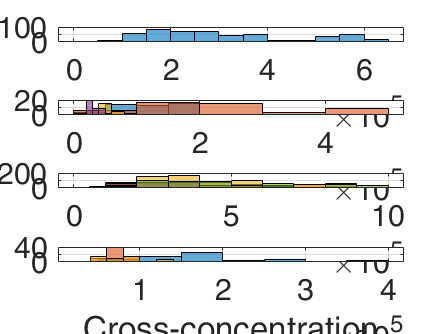


figure;
%Head
subplot 411;
c=9;%Head
histogram(conc_cross_circuit{vessels_ID(c)})
grid on
ylabel('samples');
% axis([20 90 0 1000]);
% legend('Head','Shoulder','Upper Arm','Elbow','Hand');
set(gca,'FontSize',font);

subplot 412;
%Upper Body
c=11;%Right Shoulder
histogram(conc_cross_circuit{vessels_ID(c)}); hold on;
c=15;%Right Upper Arm 
histogram(conc_cross_circuit{vessels_ID(c)});
c=21;%Right Elbow
histogram(conc_cross_circuit{vessels_ID(c)});
c=27;%Right Hand 
histogram(conc_cross_circuit{vessels_ID(c)});
grid on
% axis([20 90 0 500]);
% legend('Head','Shoulder','Upper Arm','Elbow','Hand');
set(gca,'FontSize',font);

subplot 413;
%Center Body
c=24; %Chest and back
histogram(conc_cross_circuit{vessels_ID(c)}); hold on;
c=30; %Spleen
histogram(conc_cross_circuit{vessels_ID(c)});
c=40;%Kidneys
histogram(conc_cross_circuit{vessels_ID(c)});
c=36;%Liver
histogram(conc_cross_circuit{vessels_ID(c)});
c=39;%Intestine
histogram(conc_cross_circuit{vessels_ID(c)});
c=47;%Pelvis
histogram(conc_cross_circuit{vessels_ID(c)});
grid on
% axis([20 90 0 1000]);
set(gca,'FontSize',font);

subplot 414;
%Lower Body
c=49;%Left Hip
histogram(conc_cross_circuit{vessels_ID(c)}); hold on;
c=54;%Left Knee
histogram(conc_cross_circuit{vessels_ID(c)});
c=59;%Left Foot
histogram(conc_cross_circuit{vessels_ID(c)});

grid on
% axis([20 90 0 100]);
xlabel('Cross-concentration');
set(gca,'FontSize',font);

## Saving Data for the ML model

bot=1;
c1=9;%Head
delay_Head=delay_circuit{vessels_ID(c1)};
conc_cross_Head=conc_cross_circuit{vessels_ID(c1)};
%Upper Body
c1=11;%Right Shoulder
c2=17;%Left Shoulder
delay_Shoulders=horzcat(delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
conc_cross_Shoulders=horzcat(conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
c=15;%Right Upper Arm
delay_UpperArms=horzcat(delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
conc_cross_UpperArms=horzcat(conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
c=21;%Right Elbow
delay_Elbows=horzcat(delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
conc_cross_Elbows=horzcat(conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
c=27;%Right Hand
delay_Hands=horzcat(delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
conc_cross_Hands=horzcat(conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});

%Center Body
c1=24; %Chest and back
delay_Thorax=delay_circuit{vessels_ID(c1)};
conc_cross_Thorax=conc_cross_circuit{vessels_ID(c1)};
c1=30; %Spleen
delay_Spleen=delay_circuit{vessels_ID(c1)};
conc_cross_Spleen=conc_cross_circuit{vessels_ID(c1)};
c1=40;%Kidneys
delay_Kidneys=delay_circuit{vessels_ID(c1)};
conc_cross_Kidneys=conc_cross_circuit{vessels_ID(c1)};
c1=36;%Liver
delay_Liver=delay_circuit{vessels_ID(c1)};
conc_cross_Liver=conc_cross_circuit{vessels_ID(c1)};
c1=39;%Intestine
delay_Intestine=delay_circuit{vessels_ID(c1)};
conc_cross_Intestine=conc_cross_circuit{vessels_ID(c1)};
c1=47;%Pelvis
c2=51;
delay_Pelvis=horzcat(delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
conc_cross_Pelvis=horzcat(conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});

%Lower Body
c1=49;%Left Hip
c2=52;%Right Hip
delay_Hips=horzcat(delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
conc_cross_Hips=horzcat(conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
c1=54;%Left Knee
c2=56;%Left Knee
delay_Knees=horzcat(delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
conc_cross_Knees=horzcat(conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
c1=59;%Left Feet
c2=60;%Right Feet
delay_Feet=horzcat(delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
conc_cross_Feet=horzcat(conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});

for bot=2:total_bots
    c1=9;%Head
    delay_Head=horzcat(delay_Head,delay_circuit{vessels_ID(c1)});
    conc_cross_Head=horzcat(conc_cross_Head,conc_cross_circuit{vessels_ID(c1)});
    %Upper Body
    c1=11;%Right Shoulder
    c2=17;%Left Shoulder
    delay_Shoulders=horzcat(delay_Shoulders,delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
    conc_cross_Shoulders=horzcat(conc_cross_Shoulders,conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
    c1=15;%Right Upper Arm
    c2=23;%Left Upper Arm
    delay_UpperArms=horzcat(delay_UpperArms,delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
    conc_cross_UpperArms=horzcat(conc_cross_UpperArms,conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
    c1=21;%Right Elbow
    c2=29;%Left Elbow
    delay_Elbows=horzcat(delay_Elbows,delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
    conc_cross_Elbows=horzcat(conc_cross_Elbows,conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
    c1=27;%Right Hand
    c2=33;%Right Hand
    delay_Hands=horzcat(delay_Hands,delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
    conc_cross_Hands=horzcat(conc_cross_Hands,conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});

    %Center Body
    c1=24; %Chest and back
    delay_Thorax=horzcat(delay_Thorax,delay_circuit{vessels_ID(c1)});
    conc_cross_Thorax=horzcat(conc_cross_Thorax,conc_cross_circuit{vessels_ID(c1)});
    c1=30; %Spleen
    delay_Spleen=horzcat(delay_Spleen,delay_circuit{vessels_ID(c1)});
    conc_cross_Spleen=horzcat(conc_cross_Spleen,conc_cross_circuit{vessels_ID(c1)});
    c1=40;%Kidneys
    delay_Kidneys=horzcat(delay_Kidneys,delay_circuit{vessels_ID(c1)});
    conc_cross_Kidneys=horzcat(conc_cross_Kidneys,conc_cross_circuit{vessels_ID(c1)});
    c1=36;%Liver
    delay_Liver=horzcat(delay_Liver,delay_circuit{vessels_ID(c1)});
    conc_cross_Liver=horzcat(conc_cross_Liver,conc_cross_circuit{vessels_ID(c1)});
    c1=39;%Intestine
    delay_Intestine=horzcat(delay_Intestine,delay_circuit{vessels_ID(c1)});
    conc_cross_Intestine=horzcat(conc_cross_Intestine,conc_cross_circuit{vessels_ID(c1)});
    c1=47;%Right Pelvis
    c2=51;%Left Pelvis
    delay_Pelvis=horzcat(delay_Pelvis,delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
    conc_cross_Pelvis=horzcat(conc_cross_Pelvis,conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});

    %Lower Body
    c1=49;%Left Hip
    c2=52;%Right Hip
    delay_Hips=horzcat(delay_Hips,delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
    conc_cross_Hips=horzcat(conc_cross_Hips,conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
    c1=54;%Left Knee
    c2=56;%Left Knee
    delay_Knees=horzcat(delay_Knees,delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
    conc_cross_Knees=horzcat(conc_cross_Knees,conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
    c1=59;%Left Foot
    c2=60;%Right Foot
    delay_Feet=horzcat(delay_Feet,delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
    conc_cross_Feet=horzcat(conc_cross_Feet,conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
end

save BVS_data.mat path_bot t_bot_heart t_bot_heart_lenght perd_bot_heart perd_bot_heart_length perd_bot_heart_nz perd_bot_heart_nz_length ...
     path_circuit_avg conc_bot_heart_cumul

save BVS_training_data.mat delay_Head conc_cross_Head delay_Shoulders conc_cross_Shoulders delay_UpperArms conc_cross_UpperArms ...
     delay_Elbows conc_cross_Elbows delay_Hands conc_cross_Hands delay_Thorax conc_cross_Thorax delay_Spleen conc_cross_Spleen ...
     delay_Kidneys conc_cross_Kidneys delay_Liver conc_cross_Liver delay_Intestine conc_cross_Intestine delay_Pelvis conc_cross_Pelvis ...
     delay_Hips conc_cross_Hips delay_Knees conc_cross_Knees delay_Feet conc_cross_Feet

## Plotting the delay vs cross-correlation

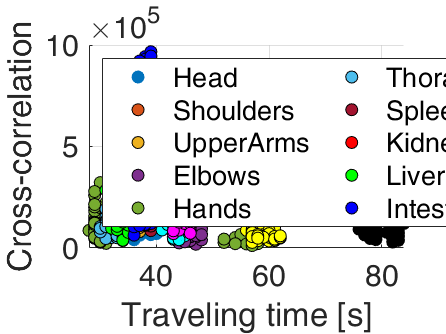

total_samples_plot=800;%total samples per circuit
figure;
color = {'#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#4DBEEE','#A2142F','#FF0000','#00FF00','#0000FF','#00FFFF','#FF00FF','#FFFF00','#000000','#FFFFFF'}; %list of colors from https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html

p9=scatter(delay_Head,conc_cross_Head,'MarkerFaceColor',color{1},'MarkerEdgeColor',color{1}); hold on;
%Upper Body
c=11;%Right Shoulder
p11=scatter(delay_Shoulders,conc_cross_Shoulders,'MarkerFaceColor',color{2},'MarkerEdgeColor','#000000');
c=15;%Right Upper Arm
p15=scatter(delay_UpperArms,conc_cross_UpperArms,'MarkerFaceColor',color{3},'MarkerEdgeColor','#000000');
c=21;%Right Elbow
p21=scatter(delay_Elbows,conc_cross_Elbows,'MarkerFaceColor',color{4},'MarkerEdgeColor','#000000');
c=27;%Right Hand
p27=scatter(delay_Hands,conc_cross_Hands,'MarkerFaceColor',color{5},'MarkerEdgeColor','#000000');


%Center Body
c=24; %Chest and back
p24=scatter(delay_Thorax,conc_cross_Thorax,'MarkerFaceColor',color{6},'MarkerEdgeColor','#000000');
c=30; %Spleen
p30=scatter(delay_Spleen,conc_cross_Spleen,'MarkerFaceColor',color{7},'MarkerEdgeColor','#000000');
c=40;%Kidneys
p40=scatter(delay_Kidneys,conc_cross_Kidneys,'MarkerFaceColor',color{8},'MarkerEdgeColor','#000000');
c=36;%Liver
p36=scatter(delay_Liver,conc_cross_Liver,'MarkerFaceColor',color{9},'MarkerEdgeColor','#000000');
c=39;%Intestine
p39=scatter(delay_Intestine,conc_cross_Intestine,'MarkerFaceColor',color{10},'MarkerEdgeColor','#000000');
c=47;%Pelvis
p47=scatter(delay_Pelvis,conc_cross_Pelvis,'MarkerFaceColor',color{11},'MarkerEdgeColor','#000000');

%Lower Body
c=49;%Left Hip
p49=scatter(delay_Hips,conc_cross_Hips,'MarkerFaceColor',color{12},'MarkerEdgeColor','#000000');hold on;
c=54;%Left Knee
p54=scatter(delay_Knees,conc_cross_Knees,'MarkerFaceColor',color{13},'MarkerEdgeColor','#000000');
c=59;%Left Foot
p59=scatter(delay_Feet,conc_cross_Feet,'MarkerFaceColor',color{14},'MarkerEdgeColor','#000000');

grid on;
legend([p9 p11 p15 p21 p27 p24 p30 p40 p36 p39 p47 p49 p54 p59],{'Head','Shoulders','UpperArms','Elbows','Hands','Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis','Hips','Knees','Feet'},'Location','northwest','NumColumns',3);
ylabel('Cross-correlation')
set(gca,'FontSize',font);
grid on;
xlabel('Traveling time [s]');

## Plotting the delay vs cross-correlation per Body Region

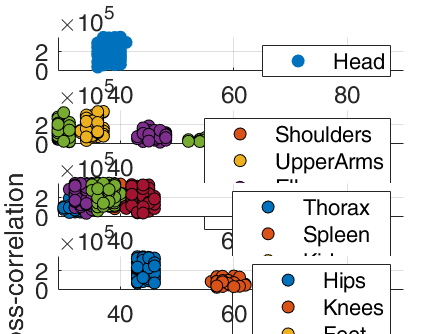

close all;
color = {'#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#4DBEEE','#A2142F','#FF0000','#00FF00','#0000FF','#00FFFF','#FF00FF','#FFFF00','#000000','#FFFFFF'}; %list of colors from https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html

font=12;
figure;
subplot 411
p9=scatter(delay_Head,conc_cross_Head,'MarkerFaceColor',color{1},'MarkerEdgeColor',color{1}); hold on;
grid on;
legend([p9],{'Head'});
set(gca,'FontSize',font);
axis([29 90 0 3.5e5]);

subplot 412
%Upper Body
c=11;%Right Shoulder
p11=scatter(delay_Shoulders,conc_cross_Shoulders,'MarkerFaceColor',color{2},'MarkerEdgeColor','#000000'); hold on;
c=15;%Right Upper Arm
p15=scatter(delay_UpperArms,conc_cross_UpperArms,'MarkerFaceColor',color{3},'MarkerEdgeColor','#000000');
c=21;%Right Elbow
p21=scatter(delay_Elbows,conc_cross_Elbows,'MarkerFaceColor',color{4},'MarkerEdgeColor','#000000');
c=27;%Right Hand
p27=scatter(delay_Hands,conc_cross_Hands,'MarkerFaceColor',color{5},'MarkerEdgeColor','#000000');
grid on;
legend([p11 p15 p21 p27],{'Shoulders','UpperArms','Elbows','Hands'});
set(gca,'FontSize',font);
axis([29 90 0 3.5e5]);

%Center Body
subplot 413
c=24; %Chest and back
p24=scatter(delay_Thorax,conc_cross_Thorax,'MarkerFaceColor',color{1},'MarkerEdgeColor','#000000'); hold on;
c=30; %Spleen
p30=scatter(delay_Spleen,conc_cross_Spleen,'MarkerFaceColor',color{2},'MarkerEdgeColor','#000000');
c=40;%Kidneys
p40=scatter(delay_Kidneys,conc_cross_Kidneys,'MarkerFaceColor',color{3},'MarkerEdgeColor','#000000');
c=36;%Liver
p36=scatter(delay_Liver,conc_cross_Liver,'MarkerFaceColor',color{4},'MarkerEdgeColor','#000000');
c=39;%Intestine
p39=scatter(delay_Intestine,conc_cross_Intestine,'MarkerFaceColor',color{5},'MarkerEdgeColor','#000000');
c=47;%Pelvis
p47=scatter(delay_Pelvis,conc_cross_Pelvis,'MarkerFaceColor',color{7},'MarkerEdgeColor','#000000');
legend([p24 p30 p40 p36 p39 p47],{'Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis'});
grid on;
set(gca,'FontSize',font);
axis([29 90 0 3.5e5]);

%Lower Body
subplot 414
c=49;%Left Hip
p49=scatter(delay_Hips,conc_cross_Hips,'MarkerFaceColor',color{1},'MarkerEdgeColor','#000000');hold on;
c=54;%Left Knee
p54=scatter(delay_Knees,conc_cross_Knees,'MarkerFaceColor',color{2},'MarkerEdgeColor','#000000');
c=59;%Left Foot
p59=scatter(delay_Feet,conc_cross_Feet,'MarkerFaceColor',color{3},'MarkerEdgeColor','#000000');
legend([p49 p54 p59],{'Hips','Knees','Feet'});

grid on;
axis([29 90 0 3.5e5]);
ylabel('Cross-correlation')
set(gca,'FontSize',font);
grid on;
xlabel('Traveling time [s]');

## Plotting cumul concentration histogram per Body Region

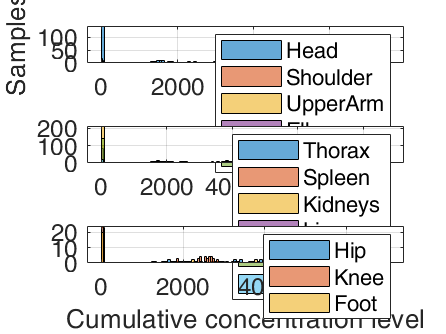

figure;
bins=100;
subplot 311
c=9;%Head
histogram(conc_cumul_circuit{vessels_ID(c)},bins); hold on;
%Upper Body
c=11;%Right Shoulder
histogram(conc_cumul_circuit{vessels_ID(c)},bins);
c=15;%Right Upper Arm 
histogram(conc_cumul_circuit{vessels_ID(c)},bins);
c=21;%Right Elbow
histogram(conc_cumul_circuit{vessels_ID(c)},bins);
c=27;%Right Hand 
histogram(conc_cumul_circuit{vessels_ID(c)},bins);
legend('Head','Shoulder','UpperArm','Elbow','Hand');
set(gca,'FontSize',font);
grid on;
% axis([0 90 0 2500]);
ylabel('Samples')

%Center Body
subplot 312
c=24; %Chest and back
histogram(conc_cumul_circuit{vessels_ID(c)},bins); hold on;
c=30; %Spleen
histogram(conc_cumul_circuit{vessels_ID(c)},bins);
c=40;%Kidneys
histogram(conc_cumul_circuit{vessels_ID(c)},bins);
c=36;%Liver
histogram(conc_cumul_circuit{vessels_ID(c)},bins);
c=39;%Intestine
histogram(conc_cumul_circuit{vessels_ID(c)},bins);
c=47;%Pelvis
histogram(conc_cumul_circuit{vessels_ID(c)},bins);
legend('Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis');
set(gca,'FontSize',font);
grid on;
% axis([0 90 0 2500]);

subplot 313
%Lower Body
c=49;%Left Hip
histogram(conc_cumul_circuit{vessels_ID(c)},bins);hold on;
c=54;%Left Knee
histogram(conc_cumul_circuit{vessels_ID(c)},bins);
c=59;%Left Foot
histogram(conc_cumul_circuit{vessels_ID(c)},bins);
legend('Hip','Knee','Foot');
set(gca,'FontSize',font);
grid on;
% axis([0 90 0 2500]);
xlabel('Cumulative concentration level');

## Plotting the delay vs cumul concentration per Body Region

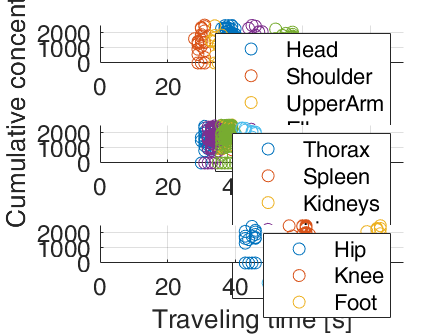


figure;

subplot 311
c=9;%Head
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)}); hold on;
%Upper Body
c=11;%Right Shoulder
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=15;%Right Upper Arm 
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=21;%Right Elbow
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=27;%Right Hand 
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
legend('Head','Shoulder','UpperArm','Elbow','Hand');
set(gca,'FontSize',font);
grid on;
axis([0 90 0 2500]);
ylabel('Cumulative concentration Level')

%Center Body
subplot 312
c=24; %Chest and back
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)}); hold on;
c=30; %Spleen
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=40;%Kidneys
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=36;%Liver
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=39;%Intestine
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=47;%Pelvis
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
legend('Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis');
set(gca,'FontSize',font);
grid on;
axis([0 90 0 2500]);

subplot 313
%Lower Body
c=49;%Left Hip
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});hold on;
c=54;%Left Knee
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=59;%Left Foot
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
legend('Hip','Knee','Foot');
set(gca,'FontSize',font);
grid on;
axis([0 90 0 2500]);
xlabel('Traveling time [s]');

## Plotting cumul concentration histogram per Body Region

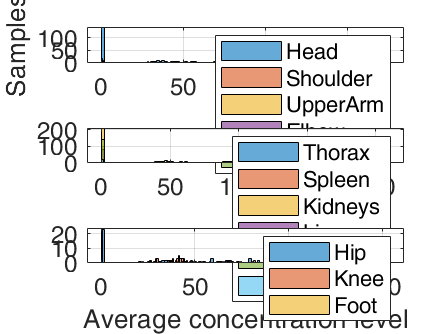

figure;
bins=100;
subplot 311
c=9;%Head
histogram(conc_avg_circuit{vessels_ID(c)},bins); hold on;
%Upper Body
c=11;%Right Shoulder
histogram(conc_avg_circuit{vessels_ID(c)},bins);
c=15;%Right Upper Arm 
histogram(conc_avg_circuit{vessels_ID(c)},bins);
c=21;%Right Elbow
histogram(conc_avg_circuit{vessels_ID(c)},bins);
c=27;%Right Hand 
histogram(conc_avg_circuit{vessels_ID(c)},bins);
legend('Head','Shoulder','UpperArm','Elbow','Hand');
set(gca,'FontSize',font);
grid on;
% axis([0 90 0 2500]);
ylabel('Samples')

%Center Body
subplot 312
c=24; %Chest and back
histogram(conc_avg_circuit{vessels_ID(c)},bins); hold on;
c=30; %Spleen
histogram(conc_avg_circuit{vessels_ID(c)},bins);
c=40;%Kidneys
histogram(conc_avg_circuit{vessels_ID(c)},bins);
c=36;%Liver
histogram(conc_avg_circuit{vessels_ID(c)},bins);
c=39;%Intestine
histogram(conc_avg_circuit{vessels_ID(c)},bins);
c=47;%Pelvis
histogram(conc_avg_circuit{vessels_ID(c)},bins);
legend('Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis');
set(gca,'FontSize',font);
grid on;
% axis([0 90 0 2500]);

subplot 313
%Lower Body
c=49;%Left Hip
histogram(conc_avg_circuit{vessels_ID(c)},bins);hold on;
c=54;%Left Knee
histogram(conc_avg_circuit{vessels_ID(c)},bins);
c=59;%Left Foot
histogram(conc_avg_circuit{vessels_ID(c)},bins);
legend('Hip','Knee','Foot');
set(gca,'FontSize',font);
grid on;
% axis([0 90 0 2500]);
xlabel('Average concentration level');

## Plotting the delay vs avg concentration per Body Region

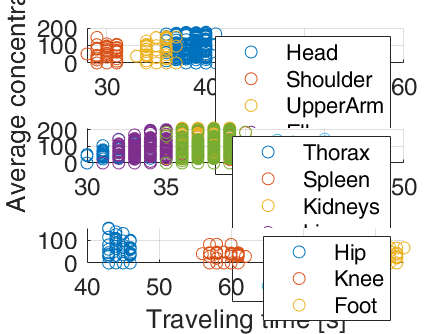


figure;

subplot 311
c=9;%Head
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)}); hold on;
%Upper Body
c=11;%Right Shoulder
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
c=15;%Right Upper Arm 
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
c=21;%Right Elbow
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
c=27;%Right Hand 
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
legend('Head','Shoulder','UpperArm','Elbow','Hand');
set(gca,'FontSize',font);
grid on;
% axis([0 90 0 2500]);
ylabel('Average concentration Level')

%Center Body
subplot 312
c=24; %Chest and back
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)}); hold on;
c=30; %Spleen
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
c=40;%Kidneys
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
c=36;%Liver
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
c=39;%Intestine
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
c=47;%Pelvis
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
legend('Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis');
set(gca,'FontSize',font);
grid on;
% axis([0 90 0 2500]);

subplot 313
%Lower Body
c=49;%Left Hip
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});hold on;
c=54;%Left Knee
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
c=59;%Left Foot
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
legend('Hip','Knee','Foot');
set(gca,'FontSize',font);
grid on;
% axis([0 90 0 2500]);
xlabel('Traveling time [s]');

## Plotting the delay vs cumul concentration 

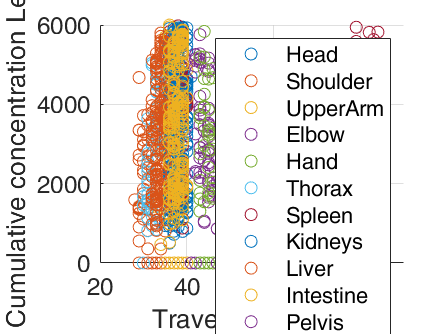


figure;


c=9;%Head
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)}); hold on;
%Upper Body
c=11;%Right Shoulder
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=15;%Right Upper Arm 
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=21;%Right Elbow
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=27;%Right Hand 
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});

set(gca,'FontSize',font);
grid on;


%Center Body

c=24; %Chest and back
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)}); hold on;
c=30; %Spleen
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=40;%Kidneys
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=36;%Liver
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=39;%Intestine
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=47;%Pelvis
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});


%Lower Body
c=49;%Left Hip
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});hold on;
c=54;%Left Knee
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=59;%Left Foot
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});

legend('Head','Shoulder','UpperArm','Elbow','Hand','Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis','Hip','Knee','Foot');
set(gca,'FontSize',font);
grid on;


axis([20 90 0 6000]);
xlabel('Traveling time [s]')
ylabel('Cumulative concentration Level');

## Visualizing data as an histogram

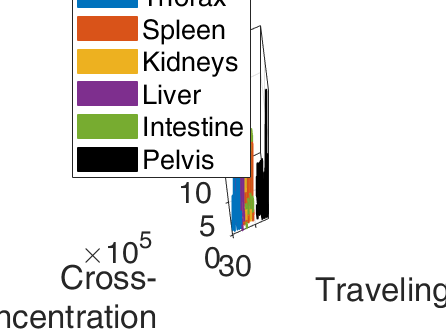

fontsize=15;
color_HEX = {'#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#000000','#4DBEEE','#FF0000','#00FF00','#0000FF','#00FFFF','#FF00FF','#FFFF00','#000000','#A2142F'}; %list of colors from https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html

%histogram resolution
bins=10;
totSampCirc=0.1*min([length(delay_Thorax) length(delay_Spleen) length(delay_Kidneys) ...
                               length(delay_Liver) length(delay_Intestine) length(delay_Pelvis)]);

%preparing data visualizing
%delay array
delay_center_body=horzcat(delay_Thorax(1:totSampCirc),delay_Spleen(1:totSampCirc),delay_Kidneys(1:totSampCirc), ...
                          delay_Liver(1:totSampCirc),delay_Intestine(1:totSampCirc),delay_Pelvis(1:totSampCirc));                   
%concentration array
conc_center_body=horzcat(conc_cross_Thorax(1:totSampCirc),conc_cross_Spleen(1:totSampCirc),conc_cross_Kidneys(1:totSampCirc),...
                    conc_cross_Liver(1:totSampCirc),conc_cross_Intestine(1:totSampCirc),conc_cross_Pelvis(1:totSampCirc));
%clustered data
dataCluster=horzcat(delay_center_body',conc_center_body')';


figure;
for i=1:6
    x1=(i-1)*totSampCirc+1;
    x2=x1+totSampCirc-1;

    h2=histogram2(dataCluster(1,x1:x2),dataCluster(2,x1:x2),bins,'FaceColor',color_HEX{i},'EdgeColor',color_HEX{i}); hold on;


end
ylabel({'Cross-','concentration'});
set(get(gca,'YLabel'),'Rotation',0)
xlabel('Traveling time [s]');
legend('Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis');
legend('Position',[0.2555,0.60318,0.21429,0.32976])
set(gca,'FontSize',fontsize)
view([-14 28]);